# AERO 557: Homework 3

#### Isaac Velasco

clc; clear; close all; beep off
addpath('..\Functions\')

### Problem 1: Pork Chop Plot

Generate a pork chop plot for the 2005 Earth to Mars opportunity. Use Earth departure dates from JD = 2453528.0 (June 6th, 2005) to 2453682.0 (Nov. 7$^\text{th}$, 2005) and Mars arrival dates from JD =2453706.0 (Dec. 1$^{\text{st}}$, 2005) to 2454156.0 (Feb. 24$^{\text{th}}$, 2007). Plot C3 at Earth (km$^2$/s$^2
$), $\text{V}_\infty$ at Mars (km/s), and time of transfer (days). The plot should look like the figure I showed you in class. Use the plot to answer the following questions. Please turn in the plot with the homework.

    a)    What do you think is the optimal departure/arrival combination for a robotic mission that wishes to minimize total ΔV without using any aerobraking? Just eyeball it – a range of answers is certainly acceptable.) Is this a Type I or a Type II trajectory?

    b)    What is the optimal departure/arrival combination for a human mission to Mars, given the maximum flight duration of 150 days? Assume that the mission will implement a direct transfer descent to the Martian surface, i.e., it will not enter into a Mars orbit. Also assume that the entry vehicle can only withstand the heat generated from a trajectory with a $\text{V}_\infty$ < 4.5 km$^2$/s$^2
$.

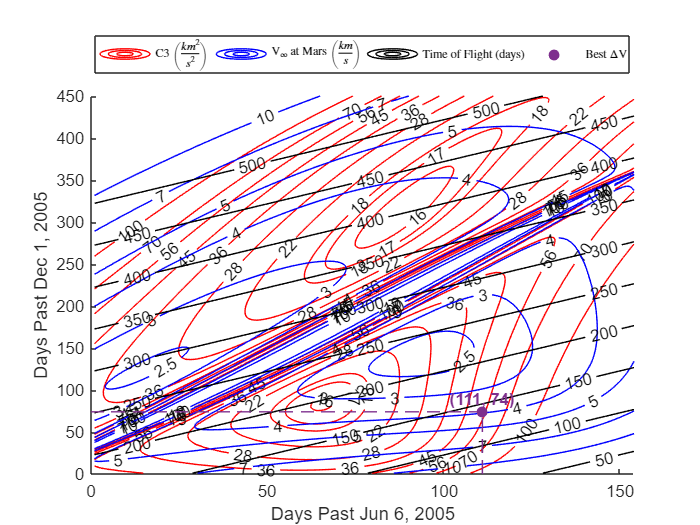

departloc        = 'Earth';
arriveloc        = 'Mars';
departtime       = [datetime(2453528.0,'convertfrom','juliandate'),...
                    datetime(2453682.0,'convertfrom','juliandate')];
arrivetime       = [datetime(2453706.0,'convertfrom','juliandate'),...
                    datetime(2454156.0,'convertfrom','juliandate')];
opts.lowerC3     = 4;
opts.upperC3     = 110;
opts.lowerVinf   = 2;
opts.upperVinf   = 10;
opts.C3levels    = [16,17,18,22,28,36,45,56,70,100];
opts.Vinflevels  = [2.5,3,4,5,7,10];
opts.TOFlevels   = 50:50:500;
opts.optimalt    = 1;
[dVshort,dVlong,bestdv,C3short,C3long,Vinfshort,Vinflong,TOF] = porkchoplot(departloc,arriveloc,departtime,arrivetime,opts);


[rf,cf] = find(TOF < 150);
stran   = zeros(size(TOF));
vshort  = zeros(size(Vinfshort));
for day = 1:length(rf)
    if Vinfshort(rf(day),cf(day)) < 4.5
        vshort(rf(day),cf(day))  = Vinfshort(rf(day),cf(day));
        stran(rf(day),cf(day))   = TOF(rf(day),cf(day));
    end
end

% find mins for constraints
[r,c] = find(vshort ==  min(nonzeros(vshort)));
fprintf('min Vinf %f\n',vshort(r,c))
fprintf('min TOF %f\n', stran(r,c));

[r,c] = find(stran ==  min(nonzeros(stran)));
fprintf('min Vinf %f\n',vshort(r,c))
fprintf('min TOF %f\n', stran(r,c));


figure
hold on
contour(TOF,50:50:150,'k','ShowText','on')
contour(Vinfshort,[2.5,3,4],'b','ShowText','on')
contour(vshort,[3,4],'m','ShowText','on')
contour(stran,[130,140],'g','ShowText','on')
xlabel('Days Past Jun 6, 2005')
ylabel('Days Past Dec 1, 2005')
legend('Time of Flight (days)','V$_\infty$ at Mars $\left(\frac{km}{s}\right)$',...
        'V$_\infty$ $<$ 4.5','TOF $<$ 150 days',...
        'Interpreter','latex','Orientation','horizontal','FontSize',9,'Location','northoutside')

### Problem 3: Optimal Orbit to maximize the final horizontal velocity

Consider a transfer in the absence of external forces with a constant 2D acceleration. Let 𝛽 = steering angle. The equations of motion are:

 
$$\ddot{x} = \cos \beta\\
\ddot{y} = \sin\beta$$


Find the maximum final horizontal velocity (𝑥̇) with an initial position ($x$ and $y$) and velocity ($\dot{x}$ and$\dot{y} = 0$) and a transfer time $=3$. The final constraints are that the final height$(y) = 1$ and final vertical velocity$(\dot{y}) = 0$.

Since the problem formation was done in class, code up using `fsolve/fmincon` and provide the final position and velocity, the initial value of the steering angle, and a plot of the steering angle over the course of the transfer.

lambda_guess = [0; -1; -1; -1];
state_cond   = [0; 0; 0; 0];
options      = optimset('Display','iter','TolFun',1.e-8,'TolX',1.e-8,'MaxIter',2000);
[x,fval,outputs] = fsolve(@fsolvefun,lambda_guess,options,state_cond);

% plot resulting steering angle
tspan   = [0 3];
options = odeset('RelTol',1e-8,'AbsTol',1e-8);
[t,s]   = ode45(@ode45fun,tspan,[state_cond; x],options);
beta = atand(s(:,8)./s(:,7)); % deg

% end state
fprintf('(x,y) = (%f,%f)\n',s(end,1),s(end,2));
fprintf('(dotx,doty) = (%f,%f)\n',s(end,3),s(end,4));
fprintf('beta(t1) = %f\n',beta(1));

% steering angle
figure
plot(t,beta)
xlabel('Time (s)',Interpreter='latex')
ylabel('$\beta$ (deg)','Interpreter','latex')

function [F] = fsolvefun(lambda, s0)

    tspan   = [0 3];
    options = odeset('RelTol',1e-8,'AbsTol',1e-8);
    [~,s]   = ode45(@ode45fun,tspan,[s0; lambda],options);

    F(1,1) = s(end,2) -1;
    F(2,1) = s(end,4);
    F(3,1) = s(end,5);
    F(4,1) = s(end,7) + 1;
    F(5,1) = s0(1);
    F(6,1) = s0(2);
    F(7,1) = s0(3);
    F(8,1) = s0(4);
end

function [dstate] = ode45fun(t,state)

    % state = [s1 s2 s3 s4 λ1 λ2 λ3 λ4]

    dstate = [state(3);...
              state(4);...
             -state(7)/sqrt(state(7)^2 + state(8)^2);...
             -state(8)/sqrt(state(7)^2 + state(8)^2);...
              0;...
              0;...
             -state(5);...
             -state(6)];
end